## b. Developing PSO code

hold off; clear; close all; clc;

Define the eggholder function

fun = @(x)(-(x(2)+47).*sin(sqrt(abs((x(1)./2) + (x(2) + 47)))) + ...
    - x(1).*sin(sqrt(abs(x(1) - (x(2) +47)))))

fun = function_handle with value:
    @(x)(-(x(2)+47).*sin(sqrt(abs((x(1)./2)+(x(2)+47))))+-x(1).*sin(sqrt(abs(x(1)-(x(2)+47)))))


% True value of global optimum (check function works) and for comparison
% later
true = fun([512, 404.2319]);

Run [`x`](https://uk.mathworks.com/help/gads/particleswarm.html#budidgf-x) `= particleswarm(`[`fun`](https://uk.mathworks.com/help/gads/particleswarm.html#budidgf_sep_budidgf-fun)`,`[`nvars`](https://uk.mathworks.com/help/gads/particleswarm.html#budidgf_sep_budidgf-nvars)`)`  where nvars is the number of dimensions.

nvars = 2;

The bounds are the search domain as given in the wikipedia page

lb = [-512,-512];
ub = [512,512];

The options as with all optimisation can be defined. The swarm size is simply the number of particles, and the number of iterations that are carried out is MaxIterations, after attempting with default parameters, I set the options to those shown below as it provided a correct solution quickly.

Generally a greater number of iterations and a greater swarm size will result in better results at the cost of computational price.

options = optimoptions('particleswarm','SwarmSize',100,MaxIterations=100);

[x, fval] = particleswarm(fun,nvars,lb,ub,options)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =   512.0000  404.2318


fval = -959.6407

error = true - fval

error = 1.0235e-08

Test for many attempts

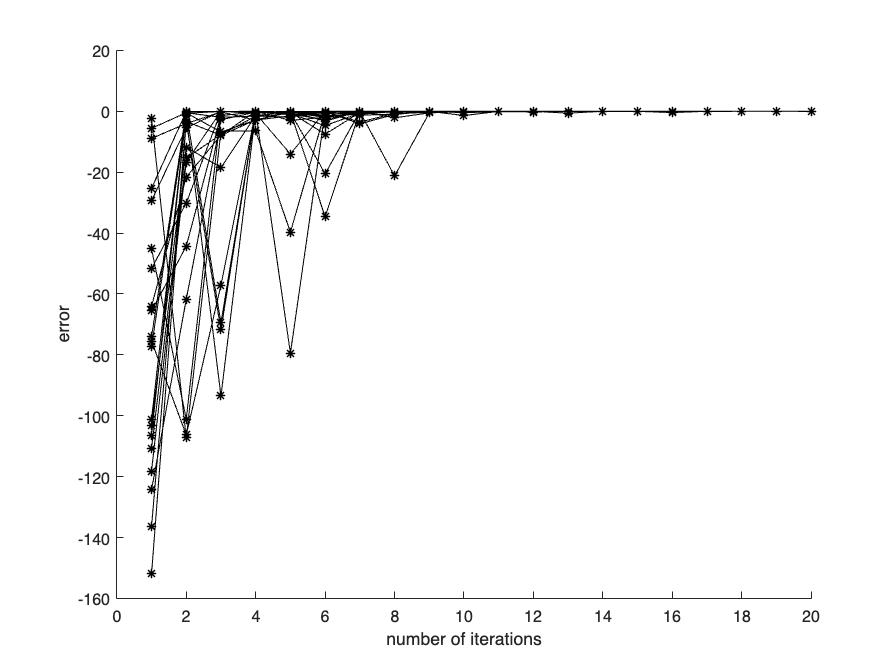

hold on;
for repeat = 1:20
    fvals = [];
    for i = 1: 20
        options = optimoptions('particleswarm','SwarmSize',200,MaxIterations=i,Display='none');
        [x, fval] = particleswarm(fun,nvars,lb,ub,options);
        fvals(i) = true - fval;
    end 
    plot(1:i,fvals,'k-',LineWidth=0.1);
    plot(1:i,fvals,'k*',LineWidth=1);
    ylabel('error');
    xlabel('number of iterations');
end
hold off;

After plotting the optimisation for 20 iterations at the same problem, you can see the stochastic property of the algorithm and also that is it is not always guaranteed to converge in the set time steps. A better measure of convergence would be the change on previous fval estimates which would stop the algorithm from diverging after attaining a zero error.

### Writing particle swarm optimisation algorithm from scratch

Because the maths seems so simple it would be interesting to compare performance of the toolbox PSO against a home made one:

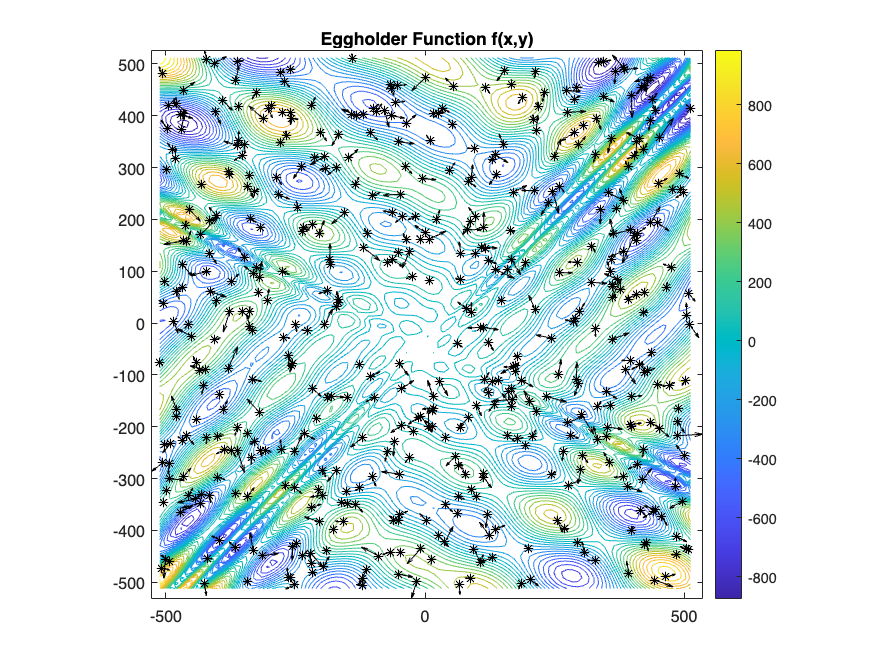

% define the inputs
num_iter = 50;
swarm_size = 500;

% plot surface
x=linspace(-512,512,100);
y=linspace(-512,512,100);
[X ,Y] = meshgrid(x,y);
egg = (-(Y+47).*sin(sqrt(abs((X./2) + (Y + 47)))) + ...
    - X.*sin(sqrt(abs(X - (Y +47)))));
contour(X,Y,egg,30); axis equal; colorbar; title('Eggholder Function f(x,y)')
hold on


% give each particle a random position in the within the bounds
X_i =(rand(2,swarm_size)*512*2)-512;

% give each particle a random velocity
V_i = randn(2,swarm_size)*0.1;

% plot points with velocities
scatter(X_i(1,:),X_i(2,:),'k*');
quiver(X_i(1,:),X_i(2,:),V_i(1,:),V_i(2,:),LineWidth=0.5,Color='black');

hold off;

This is the initial layout of particles and their respective velocities. At each iteration of the algorithm both of these properties are updated and new values stored. 

% Set coefficients
c1 = 1;
c2 = 1;
r = rand(1,2);
V_1 = zeros(2,swarm_size); 



for iter = 1:num_iter
    for i = 1:swarm_size
        % update the best values
        [pbest, pbest_val, gbest , gbest_val] = calc_bests(X_i,fun); %function found at bottom of doc
        % w as GLbestIW as described in section 4a
        w = 1.1 - (gbest_val./pbest_val(i));
        % velocities update 
        V_1(:,i) = w.*V_i(:,i) + c1.*r(1).*(pbest(:,i) - X_i(:,i)) + c2.*r(2).*(gbest - X_i(:,i));

        % location update
        X_i(:,i) = X_i(:,i) + V_1(:,i);
        % I have added this line to stop the particles escaping during the
        % optimisation, if the new coordinate is out of bounds the velocity
        % is reversed.
        if X_i(1,i) > ub(1) || X_i(1,i) < lb(1) ||  X_i(2,i) > ub(2) || X_i(2,i) < lb(2)
            X_i(:,i) = X_i(:,i) -  V_1(:,i);
        end 
    end
end

% final error
error = true - gbest_val

error = -4.7747

gbest_val, gbest

gbest_val = -954.8660

gbest =   477.6085
  433.0721


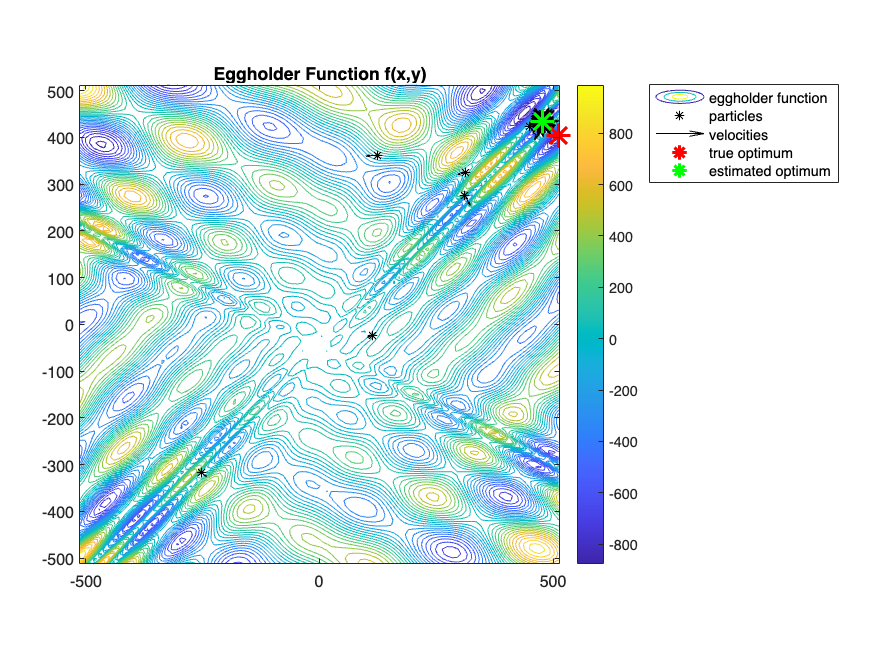

contour(X,Y,egg,30); axis equal; colorbar; title('Eggholder Function f(x,y)');
hold on
% plot points with velocities
scatter(X_i(1,:),X_i(2,:),'k*');
quiver(X_i(1,:),X_i(2,:),V_i(1,:),V_i(2,:),LineWidth=0.5,Color='black');
% true optimum
plot(512, 404.2319,'o','Marker','*','Color','red','MarkerSize',15,'LineWidth',2);
% estimated optimum
plot(gbest(1),gbest(2),'o','Marker','*','Color','green','MarkerSize',15,'LineWidth',2);
legend('eggholder function', 'particles', 'velocities', 'true optimum','estimated optimum','Location','bestoutside')
hold off;

Above is a plot of the final result after the iterations are complete. 

Below is the function to calculate the best values and positions

function [pbest, pbest_val, gbest , gbest_val] = calc_bests(X_i,fun)
% calculate global and local bests
    pbest = X_i;
    for i = 1:length(X_i)
        pbest_val(i) = fun([X_i(1,i),X_i(2,i)]);
    end
    [gbest_val, idx] = min(pbest_val);
    [gbest] = pbest(:,idx);
end

### Discussion of results

With this homemade algorithm, its clear that it has a habit of falling into local optima and converging early. Having experimented with a constant inertia weight and GLbestIW, the latter performs better on average but still runs into the same issue of converging early on not the global optimum. A decrease in the c2 coefficient slows convergence and increases the variability of results with more spread - i.e. increase individual particle exploration. 

I have also added a couple of lines to ensure that the particles do not escape the search area, I have done this by reversing the direction of the particles if a new location is about to be outside the search area. This is not mentioned in my report as I didn't think this would be an issue. However, having attempted to build PSO from scratch it is clear that this needs to be a consideration.

Even with this fairly basic code a fairly reasonable estimate of the minimum function value can be achieved, however, relative to the toolbox function with the same input parameters the result is somewhat disappointing. Even with swarm size and iterations set to a much higher value the results are not as accurate.